# Robot Arm Kinematics

 syms q1 q2 q3 q4
 L1 = 200; L2 = 250; L3 = 450; L4 = 100; % All values [mm]

L(1) = Link ( [0 -L1 0 pi/2] );
L(2) = Link ( [0 0 L2 0] );
L(3) = Link ( [0 0 L3 0] );
L(4) = Link ( [0 0 L4 0] );

 RobotArm = SerialLink(L)

 
RobotArm = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       -200|          0|     1.5708|          0|
|  2|         q2|          0|        250|          0|          0|
|  3|         q3|          0|        450|          0|          0|
|  4|         q4|          0|        100|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


 RobotArm.name = 'Hexacopter Arm';
 %RobotArm.teach

creating new ETS plot


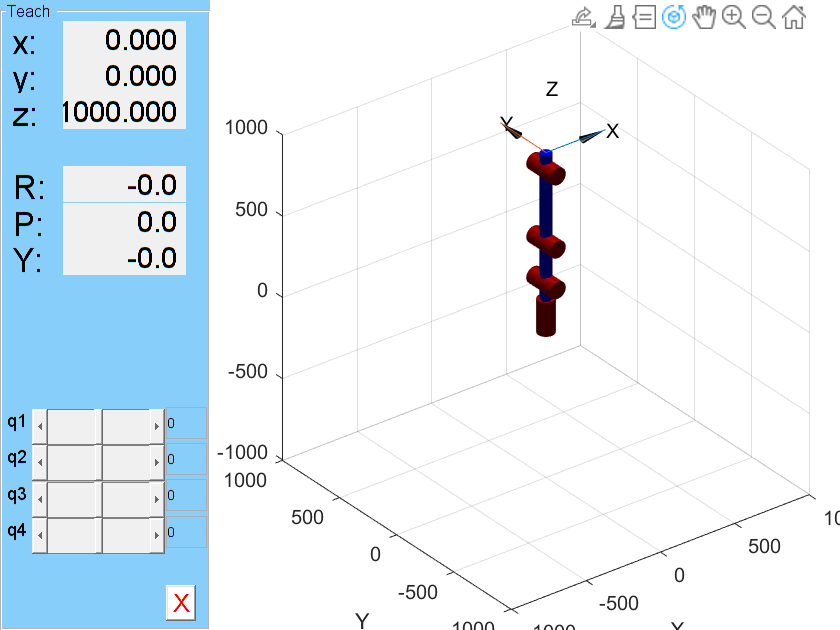

import ETS3.*
E = Rz('q1')*Tz(L1)*Ry('q2')*Tz(L2)*Ry('q3')*Tz(L3)*Ry('q4')*Tz(L4);
E.teach